
%reads the data from simulation
CL = load('Cylindrical_Results')

CL =          CORE: {2x13 cell}
            L: 1
         r2_L: [0.3000 0.4000 0.6000 0.8000 1 1.2500 1.5000 2 3 4 5 6 8]
    rangeL_r1: [1x234 double]
        total: 80000


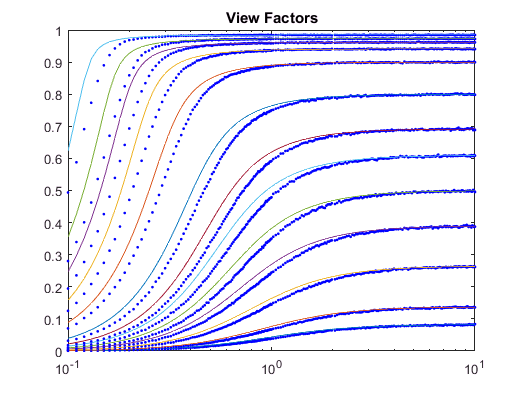

r2_L = CL.r2_L;
rangeL_r1 = CL.rangeL_r1;
h = figure('units','normalized','Name','View Factors','Position',[0.11201 0.2513 0.40996 0.54688]);
for i = 1:length(r2_L)
semilogx(CL.rangeL_r1,CL.CORE{1,i},'b.')
hold on
semilogx(CL.rangeL_r1,CL.CORE{2,i})
end
xlim([0.1,rangeL_r1(length(rangeL_r1))]);
title('View Factors')

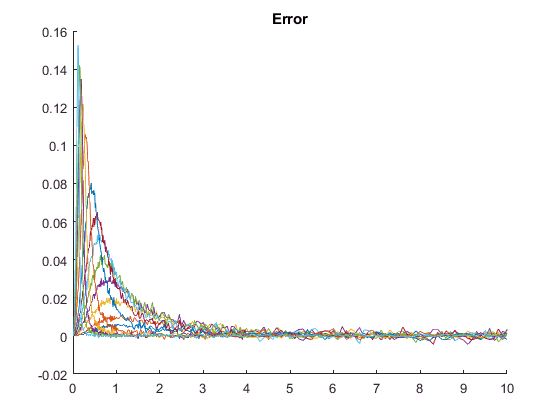

f = figure('units','pixels','Name','Error','position',[724 194 560 420]);
hold on
for i = 1:length(r2_L)
plot(CL.rangeL_r1,CL.CORE{2,i}-CL.CORE{1,i});
end

title('Error')